# Hurricane Prediction

Clear all variables.

clear;

### 1. Data Extraction

Read the data. The columns correspond to the Year, Month, Day of the Month, the Hour, the International Name of the hurricane, its Latitude, its Longitude, Wind Speed, and Pressure, respectively. 

data_extracted = readtable("WestPacific_TCdata11.csv")

data_extracted = 240750×10 table
    Var1    Var2    Var3    Var4    Var5        Var6          Var7      Var8     Var9    Var10
    ____    ____    ____    ____    ____    _____________    ______    ______    ____    _____

    1884     6       24      16      14     {'NOT_NAMED'}      16.5       124     0        0  
    1884     6       24      18      14     {'NOT_NAMED'}    16.537     123.8     0        0  
    1884     6       24      21      14     {'NOT_NAMED'}    16.598     123.5     0        0  
    1884     6       25       0      14     {'NOT_NAMED'}    16.671     123.2     0        0  
    1884     6       25       3      14     {'NOT_NAMED'

### 2. Data Preparation

Rename the column names and remove some of the columns that are non-numerical.

dim = size(data_extracted);
opts = delimitedTextImportOptions("NumVariables", dim(2));

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Year", "Month", "Day", "Hour", "HurricaneNum", "Name", "Lat", "Long", "WindSpeed", "Pressure", "NullCol"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "categorical", "double", "double", "double", "double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "NullCol", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Name", "NullCol"], "EmptyFieldRule", "auto");

data_extracted = readtable("WestPacific_TCdata11.csv",opts);

data_extracted.Date = datetime(datenum([data_extracted.Year,data_extracted.Month,data_extracted.Day]),'ConvertFrom','datenum');

% Delete the columns of information that will not be used
data = removevars(data_extracted, {'Year','Month','Day','Name', 'HurricaneNum', 'NullCol'})

data = 240750×6 table
    Hour     Lat       Long     WindSpeed    Pressure       Date    
    ____    ______    ______    _________    ________    ___________

     16       16.5       124        0           0        24-Jun-1884
     18     16.537     123.8        0           0        24-Jun-1884
     21     16.598     123.5        0           0        24-Jun-1884
      0     16.671     123.2        0           0        25-Jun-1884
      3     16.763     122.9        0           0        25-Jun-1884
      4       16.8     122.8        0           0        25-Jun-1884
      6     16.883     122.6        0           0        25-Jun-1884
      9     17.026     122.3        0           0        25-Jun-1884
     12     17.183       122        0           0        25-Jun-1884
     15     17

dim = size(data)

dim =       240750           6


Create a unique key for all of the hurricanes. This will allow us to create a category for each of the data.

data.unique_key = strcat(string(data_extracted.Name),'-',num2str(data_extracted.Year),'-',string(data_extracted.HurricaneNum));
data

data = 240750×7 table
    Hour     Lat       Long     WindSpeed    Pressure       Date            unique_key     
    ____    ______    ______    _________    ________    ___________    ___________________

     16       16.5       124        0           0        24-Jun-1884    "NOT_NAMED-1884-14"
     18     16.537     123.8        0           0        24-Jun-1884    "NOT_NAMED-1884-14"
     21     16.598     123.5        0           0        24-Jun-1884    "NOT_NAMED-1884-14"
      0     16.671     123.2        0           0        25-Jun-1884    "NOT_NAMED-1884-14"
      3     16.763     122.9        0           0        25-Jun-1884    "NOT_NAMED-1884-14"
      4       16.8     122.8        0           0        25-Jun-1884    "NOT_NAMED-1884-14"
   

Reorder variables.

oldvariables = data.Properties.VariableNames;
newvariables = ["unique_key", "Date", "Hour", "Lat", "Long", "WindSpeed", "Pressure"];
[~,LOCB] = ismember(newvariables,oldvariables);
data = data(:,LOCB);
data

data = 240750×7 table
        unique_key            Date        Hour     Lat       Long     WindSpeed    Pressure
    ___________________    ___________    ____    ______    ______    _________    ________

    "NOT_NAMED-1884-14"    24-Jun-1884     16       16.5       124        0           0    
    "NOT_NAMED-1884-14"    24-Jun-1884     18     16.537     123.8        0           0    
    "NOT_NAMED-1884-14"    24-Jun-1884     21     16.598     123.5        0           0    
    "NOT_NAMED-1884-14"    25-Jun-1884      0     16.671     123.2        0           0    
    "NOT_NAMED-1884-14"    25-Jun-1884      3     16.763     122.9        0           0    
    "NOT_NAMED-1884-14"    25-Jun-1884      4       16.8     122.8        0           0    
   

Delete rows where "Pressure" is equal to zero.

toDelete = data.Pressure == 0;
data(toDelete,:) = [];
size(data)

ans =        34581           7


Delete any rows with any elements in the "Lat" column with NaN.

toDelete = isnan(data.Lat) == 1;
data(toDelete,:) = [];
size(data)

ans =        34581           7


### 3. Counting the Number of Hurricanes

Determine total number of hurricanes in the dataset.

total_hurricane_count = length(unique(data.unique_key))

total_hurricane_count = 628

Make a list of hurricane names and count the number of instances for each hurricane name.

[hurricane_names,~,B] = unique(data.unique_key);
hurricane_names_count = histc(B,1:numel(hurricane_names));

Create an array for the names and the count.

hurricane_data = [hurricane_names hurricane_names_count]

hurricane_data = 628×2 string array
    "AERE-2004-56"            "71" 
    "AERE-2011-23"            "53" 
    "AERE-2016-79"            "77" 
    "AMPIL-2018-43"           "50" 
    "ATSANI-2015-61"          "89" 
    "ATSANI-2020-100"         "55" 
    "BAILU-2019-48"           "57" 
    "BANYAN-2005-44"          "54" 
    "BANYAN-2011-78"          "51" 
    "BANYAN-2017-57"          "55" 
    "BARIJAT-2018-79"         "43" 
    "BAVI-2002-77"            "37" 
    "BAVI-2008-82"            "21" 
    "BAVI-2015-17"            "71" 
    "BAVI-2020-62"            "53" 
    "BEBINCA-2006-77"         "25" 
    "BEBINCA-2013-28"         "35" 
    "BEBINCA-2018-59"         "63" 
    "BILIS-2006-31"           "61" 
    "BOLAVEN-2005-104"        "71" 
    "BOLAVEN-2012-50"         "85" 
    "BOLAVEN-2018-106"        "29" 
    "BOPHA-2006-46"           "49" 
    "BOPHA-2012-86"           "103"
    "BUALOI-2019-83"          "67" 
    "BULBUL:MATMO-2019-92"    "109"
    "CEMPAKA-2021-46"       

Sort from highest number of instances to the lowest.

[~,idx] = sort(str2double(hurricane_data(:,2)),'descend');
for i = 1:20
    longest = [hurricane_names(idx(i)),hurricane_names_count(idx(i))]
end

longest = 1×2 string array
    "KILO-2015-63"    "203"


longest = 1×2 string array
    "GENEVIEVE-2014-47"    "173"


longest = 1×2 string array
    "IOKE-2006-50"    "173"


longest = 1×2 string array
    "HALOLA-2015-41"    "160"


longest = 1×2 string array
    "NOT_NAMED-2013-87"    "159"


longest = 1×2 string array
    "USAGI-2018-105"    "157"


longest = 1×2 string array
    "NORU-2017-44"    "150"


longest = 1×2 string array
    "NOT_NAMED-2019-2"    "149"


longest = 1×2 string array
    "LUPIT-2003-98"    "143"


longest = 1×2 string array
    "PARMA-2009-74"    "143"


longest = 1×2 string array
    "KUJIRA-2003-23"    "139"


longest = 1×2 string array
    "HECTOR-2018-51"    "131"


longest = 1×2 string array
    "NARI-2001-58"    "126"


longest = 1×2 string array
    "DURIAN-2006-93"    "123"


longest = 1×2 string array
    "ELE-2002-54"    "123"


longest = 1×2 string array
    "NANGKA-2015-40"    "122"


longest = 1×2 string array
    "CHABA-2004-55"    "118"


longest = 1×2 string array
    "HUKO-2002-85"    "117"


longest = 1×2 string array
    "NESAT-2005-30"    "117"


longest = 1×2 string array
    "DORA-1999-55"    "113"


longest = [hurricane_names(idx(:))]

longest = 628×1 string array
    "KILO-2015-63"
    "GENEVIEVE-2014-47"
    "IOKE-2006-50"
    "HALOLA-2015-41"
    "NOT_NAMED-2013-87"
    "USAGI-2018-105"
    "NORU-2017-44"
    "NOT_NAMED-2019-2"
    "LUPIT-2003-98"
    "PARMA-2009-74"
    "KUJIRA-2003-23"
    "HECTOR-2018-51"
    "NARI-2001-58"
    "DURIAN-2006-93"
    "ELE-2002-54"
    "NANGKA-2015-40"
    "CHABA-2004-55"
    "HUKO-2002-85"
    "NESAT-2005-30"
    "DORA-1999-55"
    "SINLAKU-2008-63"
    "HALONG-2014-49"
    "LIONROCK-2016-50"
    "DOLPHIN-2015-28"
    "IN-FA-2021-44"
    "SUDAL-2004-18"
    "BULBUL:MATMO-2019-92"
    "CHATAAN-2002-30"
    "CIMARON-2006-85"
    "OMAIS-2021-59"


Delete hurricanes with less than 6 and more than 200 data points.

dim = size(hurricane_data);
for i = 1:dim(1)
    if (hurricane_names_count(i) <= 6) || (hurricane_names_count(i) >= 200)
        toDelete = data.unique_key == hurricane_names(i);
        data(toDelete,:) = [];
    end
end
dim2 = size(data)

dim2 =        34353           7


### 4. Data Preprocessing and Checking

Creates two new columns for distance (in miles) and direction.

Latitude = data.Lat;
Longitude = data.Long;
data.Distance = zeros(dim2(1),1);
data.Direction = zeros(dim2(1),1);
j = 2; 
dist = 0;
k = 1;
for i = 2:dim2(1)
    if j == 1
        data.Distance(i) = 0;
        data.Direction(i) = 0;
        j = j + 1;
    else
        if data.unique_key(i) == data.unique_key(i-1)
            [data.Distance(i), data.Direction(i)] = greatCircleDistance(Latitude(i-1),Longitude(i-1),Latitude(i),Longitude(i));
            data.Distance(i) = 0.621371*data.Distance(i); % unit conversion from km to miles
            dist = dist + data.Distance(i);
            j = j + 1;
        else
            j = 2;
            hurricane_distance(k,:) = [data.unique_key(i-1) dist];
            k = k + 1;
            dist = 0;
        end
    end
end

Display data with direction in miles and direction in degrees.

data

data = 34353×9 table
       unique_key           Date        Hour     Lat       Long     WindSpeed    Pressure    Distance    Direction
    _________________    ___________    ____    ______    ______    _________    ________    ________    _________

    "ENRIQUE-1991-40"    15-Jul-1991     12        9.4     248.1       25          1008            0           0  
    "ENRIQUE-1991-40"    15-Jul-1991     15     9.5977    247.41       27          1007       48.637       43.58  
    "ENRIQUE-1991-40"    15-Jul-1991     18        9.8     246.7       30          1007       50.662      39.839  
    "ENRIQUE-1991-40"    15-Jul-1991     21     10.008    245.94       32          1006       53.

Determine minimum and maximum values of "Lat" and "Long" for geoplot.

min(data.Lat)

ans = 0.3850

max(data.Lat)

ans = 51.3800

min(data.Long)

ans = 56

max(data.Long)

ans = 262.9000

Determine total distance travelled by hurricane in miles.

size(hurricane_distance)

ans =    618     2


hurricane_distance

hurricane_distance = 618×2 string array
    "ENRIQUE-1991-40"      "2051.3599"
    "JOHN-1994-64"         "3867.0283"
    "DORA-1999-55"         "5390.79"  
    "CIMARON-2001-21"      "1798.142" 
    "CHEBI-2001-26"        "2138.9236"
    "DURIAN-2001-29"       "1009.5018"
    "UTOR-2001-30"         "2280.5996"
    "TRAMI-2001-31"        "1023.3796"
    "KONG-REY-2001-37"     "1962.2382"
    "YUTU-2001-38"         "1241.2603"
    "TORAJI-2001-39"       "1535.5056"
    "MAN-YI-2001-40"       "3049.9227"
    "USAGI-2001-43"        "1016.8274"
    "PABUK-2001-44"        "2447.1714"
    "NOT_NAMED-2001-49"    "370.0513" 
    "WUTIP-2001-50"        "1905.8642"
    "SEPAT-2001-51"        "1673.6195"
    "FITOW-2001-53"        "623.4515" 
    "DANAS-2001-55"        "2548.4914"
    "NARI-2001-58"         "1941.0763"
    "VIPA-2001-63"         "2184.7747"
    "FRANCISCO-2001-64"    "2991.6596"
    "LEKIMA-2001-67"       "820.8847" 
    "KROSA-2001-73"        "2313.4319"
    "HAIYAN-2001-80"    

Plot hurricane tracks on geographic map per hurricane.

figure
dim3 = size(hurricane_distance);
num_hurricanes = dim3(1)

num_hurricanes = 618

Plot the first five hurricanes.

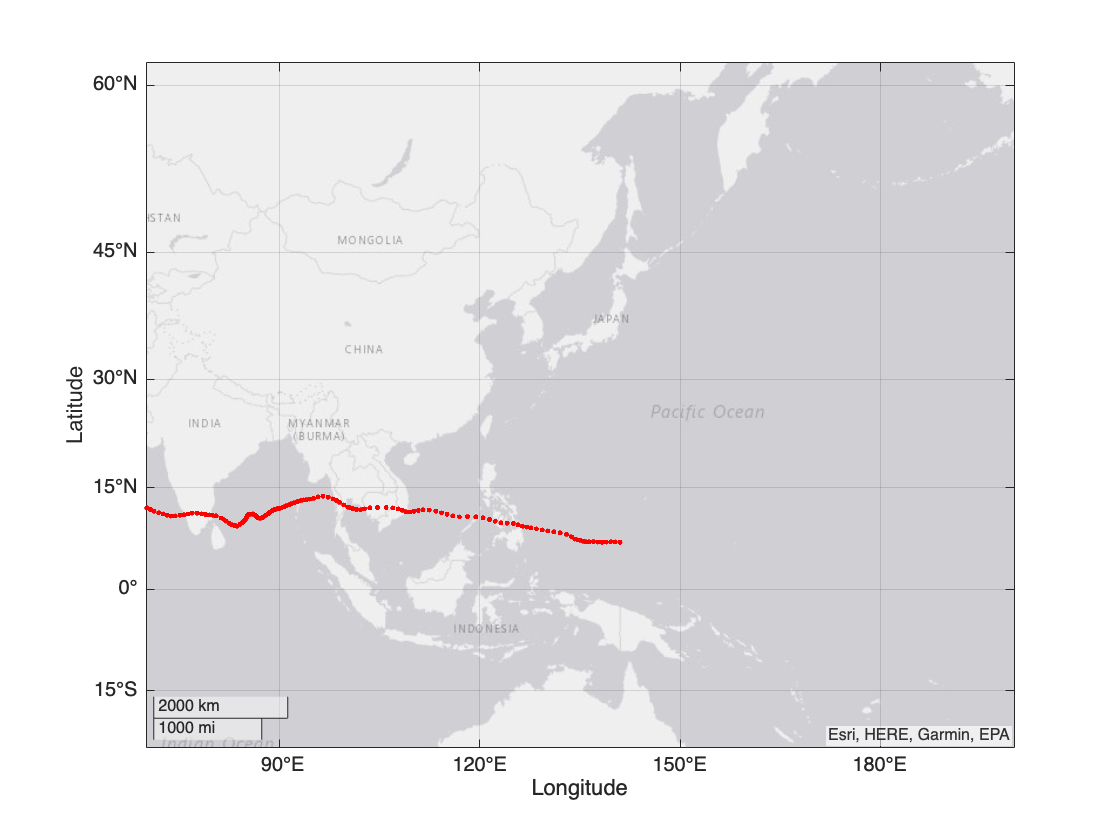

for i = 1:5
    lat_coor = data.Lat(data.unique_key == hurricane_distance(i));
    long_coor = data.Long(data.unique_key == hurricane_distance(i));
      lat_coor = data.Lat(data.unique_key == longest(i));
      long_coor = data.Long(data.unique_key == longest(i));
      name = longest(i);
    for j = 1:length(lat_coor)
       geoplot(lat_coor(j),long_coor(j),'r.-')
        geolimits([-20 60],[70 200])
        %textm(-60, 45, name);%,"HorizontalAlignment","left","VerticalAlignment","top")
        hold on
       pause(0.02)
    end
    hold off
end

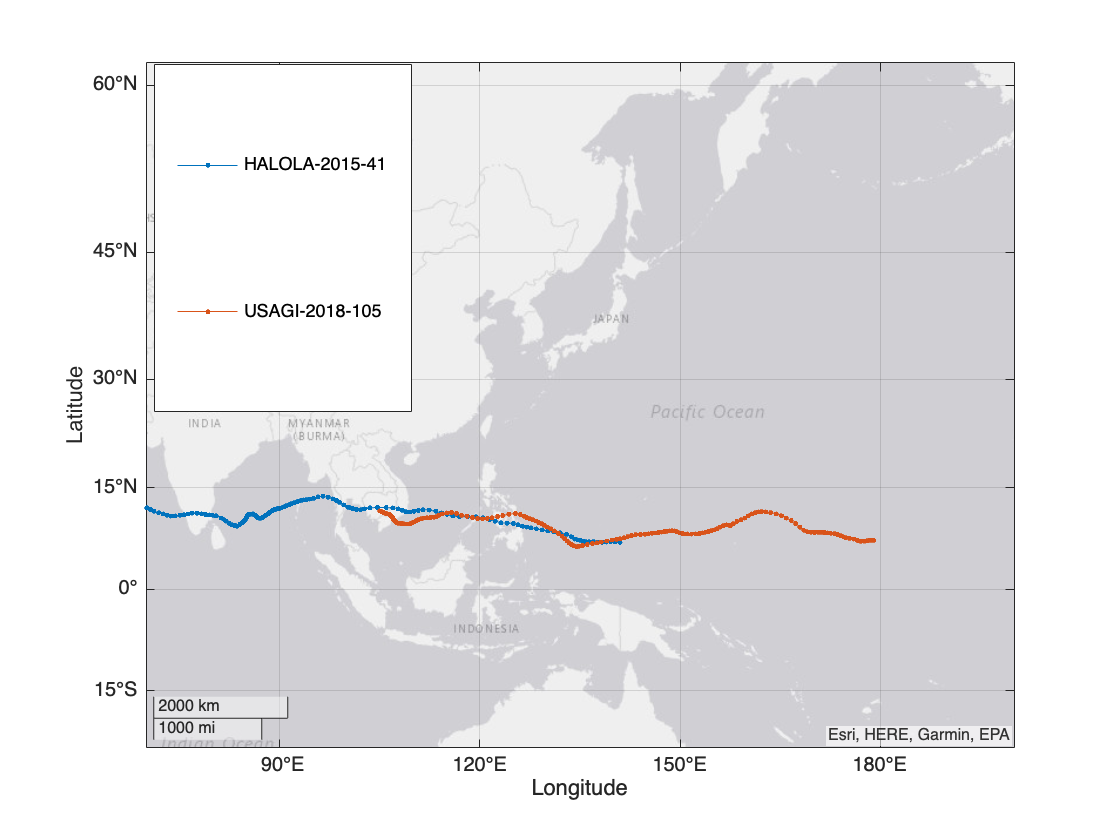

for i = 5:6

      lat_coor = data.Lat(data.unique_key == longest(i));
      long_coor = data.Long(data.unique_key == longest(i));

       geoplot(lat_coor,long_coor,'.-')
       %set(gca,'MLineLocation',1,'PLineLocation',1)
      
        hold on
        
end
        geolimits([-20 60],[70 200])
        %pause(0.05)

 legend (longest(4),longest(6))
    hold off

legend("Position",[0.13775,0.50971,0.22946,0.4131])

Plot all hurricane tracks on geographic map.

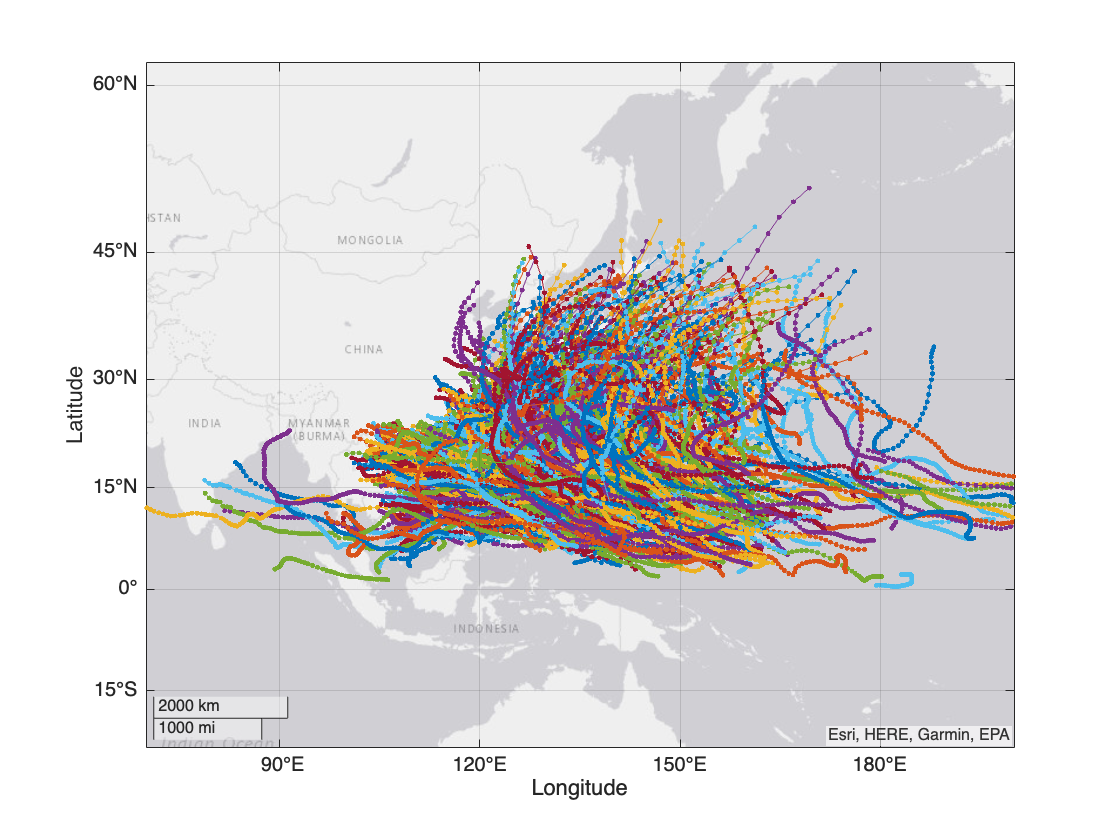

for i = 1:num_hurricanes
    lat_coor = data.Lat(data.unique_key == hurricane_distance(i));
    long_coor = data.Long(data.unique_key == hurricane_distance(i));
    geoplot(lat_coor,long_coor,'.-')
    hold on
end
geolimits([-20 60],[70 200])
hold off

Show data with direction in miles and direction in degrees.

data

data = 34353×9 table
       unique_key           Date        Hour     Lat       Long     WindSpeed    Pressure    Distance    Direction
    _________________    ___________    ____    ______    ______    _________    ________    ________    _________

    "ENRIQUE-1991-40"    15-Jul-1991     12        9.4     248.1       25          1008            0           0  
    "ENRIQUE-1991-40"    15-Jul-1991     15     9.5977    247.41       27          1007       48.637       43.58  
    "ENRIQUE-1991-40"    15-Jul-1991     18        9.8     246.7       30          1007       50.662      39.839  
    "ENRIQUE-1991-40"    15-Jul-1991     21     10.008    245.94       32          1006       53.

Create "gridID".

lat_min = min(data.Lat)

lat_min = 0.3850

long_min = min(data.Long)

long_min = 56

lat_interval = round(max(data.Lat) - lat_min)

lat_interval = 51

long_interval = round(max(data.Long) + long_min)

long_interval = 319

data.gridID = floor(data.Lat - lat_min) * long_interval  + floor(data.Long - long_min)

data = 34353×10 table
       unique_key           Date        Hour     Lat       Long     WindSpeed    Pressure    Distance    Direction    gridID
    _________________    ___________    ____    ______    ______    _________    ________    ________    _________    ______

    "ENRIQUE-1991-40"    15-Jul-1991     12        9.4     248.1       25          1008            0           0       3063 
    "ENRIQUE-1991-40"    15-Jul-1991     15     9.5977    247.41       27          1007       48.637       43.58       3062 
    "ENRIQUE-1991-40"    15-Jul-1991     18        9.8     246.7       30          1007       50.662      39.839       3061 
    "ENRIQUE

data.gridID = round(data.gridID)

data = 34353×10 table
       unique_key           Date        Hour     Lat       Long     WindSpeed    Pressure    Distance    Direction    gridID
    _________________    ___________    ____    ______    ______    _________    ________    ________    _________    ______

    "ENRIQUE-1991-40"    15-Jul-1991     12        9.4     248.1       25          1008            0           0       3063 
    "ENRIQUE-1991-40"    15-Jul-1991     15     9.5977    247.41       27          1007       48.637       43.58       3062 
    "ENRIQUE-1991-40"    15-Jul-1991     18        9.8     246.7       30          1007       50.662      39.839       3061 
    "ENRIQUE

### 5. Prepare training data and target data sets.

remove non-relevant variables

learning_data = removevars(data, ["Date","Hour","Lat","Long"])

learning_data = 34353×6 table
       unique_key        WindSpeed    Pressure    Distance    Direction    gridID
    _________________    _________    ________    ________    _________    ______

    "ENRIQUE-1991-40"       25          1008            0           0       3063 
    "ENRIQUE-1991-40"       27          1007       48.637       43.58       3062 
    "ENRIQUE-1991-40"       30          1007       50.662      39.839       3061 
    "ENRIQUE-1991-40"       32          1006       53.482      77.001       3060 
    "ENRIQUE-1991-40"       35          1005       52.261      141.61       3060 
    "ENRIQUE-1991-40"       40          1003        46.91      157.97       3059 
    "ENRIQUE-1991-40"       45          1001       43.852      158.67       3377 
    "ENRIQUE-1991-40"      

Convert data structure to array.

learning_dataset = table2array(learning_data(:,2:end));
dim4  = size(learning_dataset)

dim4 =        34353           5


Initialize variables XData and YData.

XData = zeros(size(learning_data,2)-2, size(learning_data,1));%-num_hurricanes);
size(XData)

ans =            4       34353


YData = zeros(1, size(learning_data,1));% - num_hurricanes);
size(YData)

ans =            1       34353


## **Normalization of Dataset**

numFeatures = size(XData,1)

numFeatures = 4

XData = transpose(learning_dataset(:,1:dim4(2)-1));
YData = transpose(learning_dataset(:,dim4(2)));

% Scaling
% mux = mean(XData,2);
% sigx = std(XData,0,2);
% XData = (XData - mux) ./ sigx
% muy = mean(YData);
% sigy = std(YData);
% YData = (YData - muy) ./ sigy

% Min-Max Scaling
XData = (XData - min(XData))./(max(XData)-min(XData))

XData =     0.0248         0         0         0         0         0    0.0012    0.0045    0.0455    0.0065    0.0065    0.0050    0.0064    0.0095    0.0118    0.0076    0.0039    0.0002         0         0         0         0         0         0         0         0         0         0    0.0109    0.0097    0.0008         0         0         0         0         0         0         0         0    0.0034    0.0089    0.0079    0.0074    0.0122    0.0166    0.0207    0.0186    0.0098    0.0014         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000 

YData = (YData - min(YData))./(max(YData)-min(YData))

YData =     0.1845    0.1845    0.1844    0.1844    0.1844    0.1843    0.2042    0.2042    0.2042    0.2042    0.2241    0.2241    0.2241    0.2240    0.2439    0.2439    0.2438    0.2438    0.2438    0.2637    0.2636    0.2636    0.2635    0.2635    0.2634    0.2634    0.2833    0.2833    0.2833    0.2832    0.2832    0.2832    0.3032    0.2831    0.2831    0.2830    0.2830    0.2830    0.2829    0.2829    0.2829    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3028    0.3228


## **Set percent split between training and test data sets.**

Use 85% of the data as traing set, and the remaining 15% as test set

split = 0.85;
idx_split = round(split*dim4(1))

idx_split = 29200

% transposing so that the feature size is the length of the row vector
% and the time sequence is the column vector
XTrain = XData(:,1:idx_split);
size(XTrain)

ans =            4       29200


YTrain = YData(:,1:idx_split);
size(YTrain)

ans =            1       29200


XTest = XData(:,idx_split+1:end);
size(XTest)

ans =            4        5153


YTest = YData(:,idx_split+1:end);
size(YTest)

ans =            1        5153


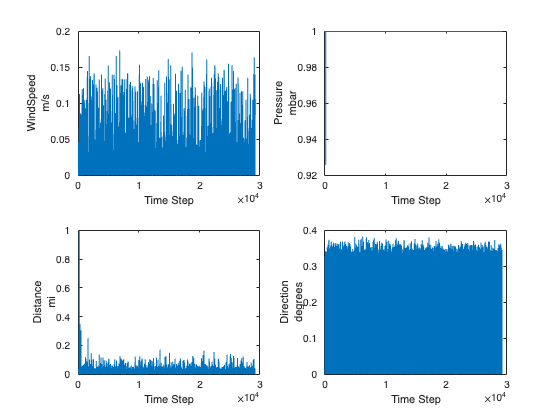

figure
units = ["m/s","mbar","mi","degrees"];
for i = 1:4
    subplot(2,2,i)
    plot(XTrain(i,:))
    ylabel({string(learning_data.Properties.VariableNames{i+1}); units(i)});
    xlabel("Time Step")
end

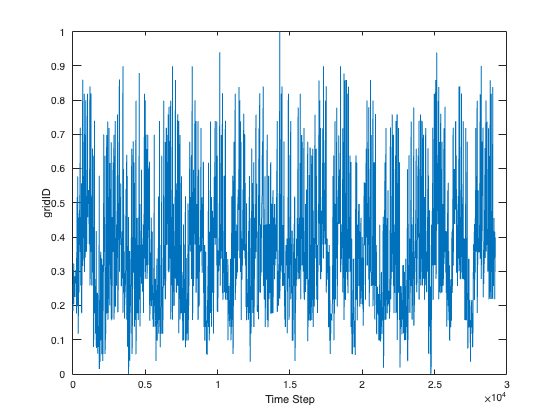

figure
plot(YTrain)
ylabel(string(learning_data.Properties.VariableNames{6}))
xlabel("Time Step")

### 6. Define the network architecture

Define the network architecture. Create an LSTM network that consists of an LSTM layer with 200 hidden units, followed by a fully connected layer of size 50 and a dropout layer with dropout probability 0.5, and a regression Layer

numResponses = size(YTrain,1);
numHiddenUnits = round(split*200);

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(50)
    dropoutLayer(0.1)
    lstmLayer(numHiddenUnits,'OutputMode','sequence')
    fullyConnectedLayer(50)
    dropoutLayer(0.1)
%     lstmLayer(numHiddenUnits,'OutputMode','sequence')
%     fullyConnectedLayer(50)
%     dropoutLayer(0.1)
%     lstmLayer(numHiddenUnits,'OutputMode','sequence')
%     fullyConnectedLayer(1)
%     dropoutLayer(0.1)
    fullyConnectedLayer(numResponses)
    tanhLayer
    regressionLayer
    ];

Specify the training options. Train for 60 epochs with mini-batches of size 20 using the solver `'adam'`. Specify the learning rate 0.01. To prevent the gradients from exploding, set the gradient threshold to 1. To keep the sequences sorted by length, set `'Shuffle'` to `'never'`.

maxEpochs = 60;
miniBatchSize = 20;
verbFreq = 1;

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'InitialLearnRate',0.01, ...
    'GradientThreshold',1, ...
    'Shuffle','never', ...
    'Plots','training-progress',...
    'ValidationData',{XTest,YTest},...
    'ValidationFrequency',10,...
    'Verbose',1, ...
    "VerboseFrequency",verbFreq);

### 7. Train the Network

Train the network using trainNetwork.

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:36 |         0.39 |         0.67 |       0.0765 |       0.2229 |          0.0100 |
|       2 |           2 |       00:01:06 |         0.66 |              |       0.2183 |              |          0.0100 |
|       3 |           3 |       00:01:35 |         1.27 |              |       0.8067 |              |          0.0100 |
|       4 |           4 |       00:02:03 |         0.26 |              |       0.0346 |              |          0.0100 |
|       

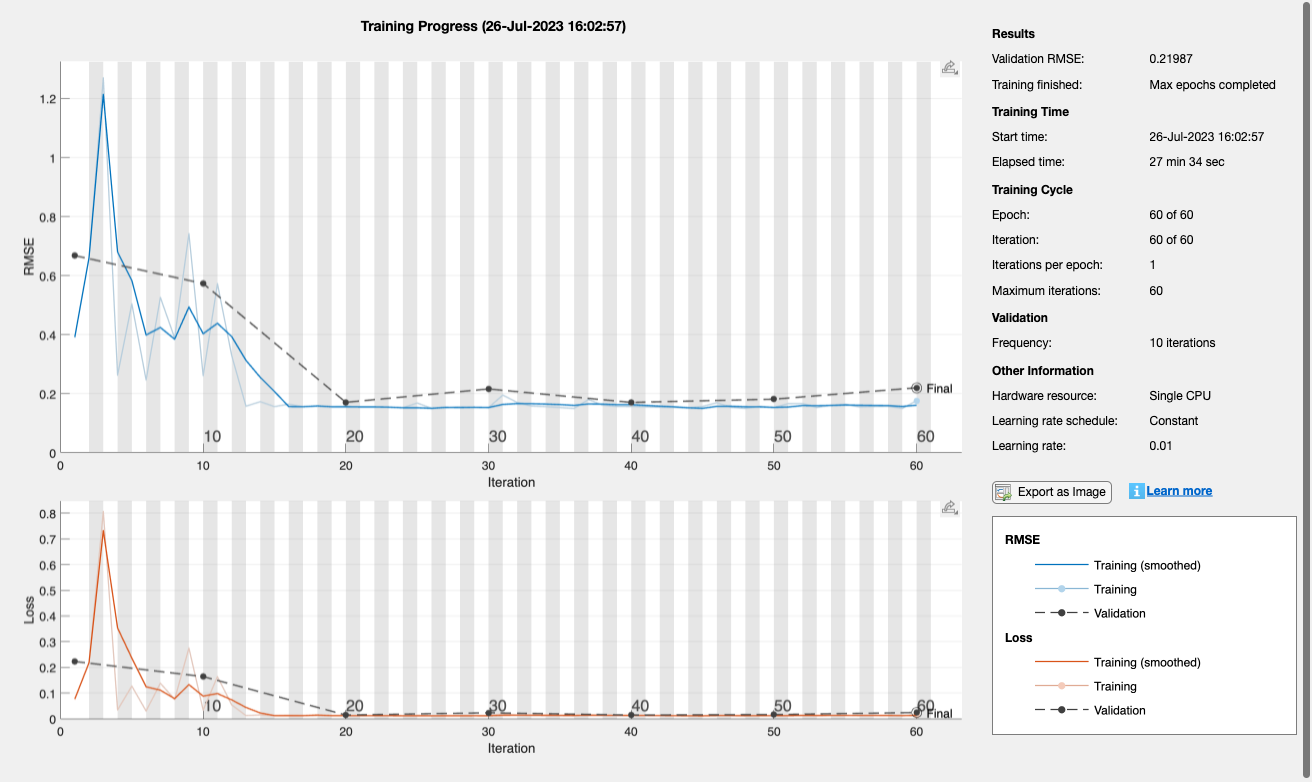

[net, info] = trainNetwork(XTrain,YTrain,layers,options);

### 8. Test and Assess the Network

Make predictions on the test data using `predict`. To prevent the function from adding padding to the data, specify the mini-batch size 1.

YPred = predict(net,XTest,'MiniBatchSize',1);

Compare between predicted and test outputs.

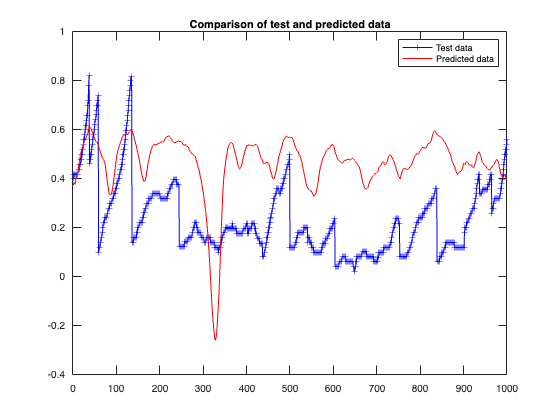

numdatapts = 1000; % length(YPred);
figure
    plot(YTest(1:numdatapts),'b+-')
    hold on
    plot(YPred(1:numdatapts),'r')
    legend ('Test data','Predicted data')
    title ('Comparison of test and predicted data')
    hold off


% figure
% count = floor(sqrt(round(length(YTest)/200)));
% for i = 1:count^2
%     subplot(count,count,i)
%     plot(YTest((i-1)*200+1:i*200),'b+-')
%     hold on
%     plot(YPred((i-1)*200+1:i*200),'r')
%     hold off
% end

Determine RMSE

figure
rmse = sqrt(mean((YPred - YTest).^2))

rmse = single
0.2199

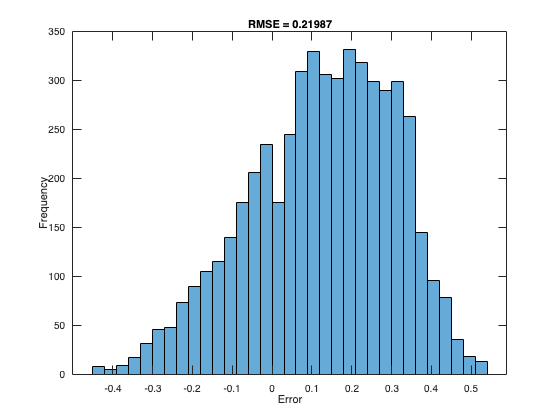

histogram(YPred - YTest)
title("RMSE = " + rmse)
ylabel("Frequency")
xlabel("Error")

Check the error for each hurricane.

% list of all hurricane names
%hurricane_distance
hurricane_data

hurricane_data = 628×2 string array
    "AERE-2004-56"            "71" 
    "AERE-2011-23"            "53" 
    "AERE-2016-79"            "77" 
    "AMPIL-2018-43"           "50" 
    "ATSANI-2015-61"          "89" 
    "ATSANI-2020-100"         "55" 
    "BAILU-2019-48"           "57" 
    "BANYAN-2005-44"          "54" 
    "BANYAN-2011-78"          "51" 
    "BANYAN-2017-57"          "55" 
    "BARIJAT-2018-79"         "43" 
    "BAVI-2002-77"            "37" 
    "BAVI-2008-82"            "21" 
    "BAVI-2015-17"            "71" 
    "BAVI-2020-62"            "53" 
    "BEBINCA-2006-77"         "25" 
    "BEBINCA-2013-28"         "35" 
    "BEBINCA-2018-59"         "63" 
    "BILIS-2006-31"           "61" 
    "BOLAVEN-2005-104"        "71" 
    "BOLAVEN-2012-50"         "85" 
    "BOLAVEN-2018-106"        "29" 
    "BOPHA-2006-46"           "49" 
    "BOPHA-2012-86"           "103"
    "BUALOI-2019-83"          "67" 
    "BULBUL:MATMO-2019-92"    "109"
    "CEMPAKA-2021-46"       

%size(hurricane_distance)
size(hurricane_data)

ans =    628     2


## Plotting hurricane predictions

% select a hurricane name
% the hurricane name must cover the last 15% of the dataset
% due to the splitting of the data
% otherwise, the variable index will be negative
% and there will be a plotting error
% the index of 525 is the lowest index in this case
name = hurricane_distance(527)

name = "KONG-REY-2018-92"

%name = hurricane_distance(427)
idx = find(data.unique_key == name)

idx =        29259
       29260
       29261
       29262
       29263
       29264
       29265
       29266
       29267
       29268


index = (size(YTest,2) - (dim4(1)-idx))

index =     59
    60
    61
    62
    63
    64
    65
    66
    67
    68


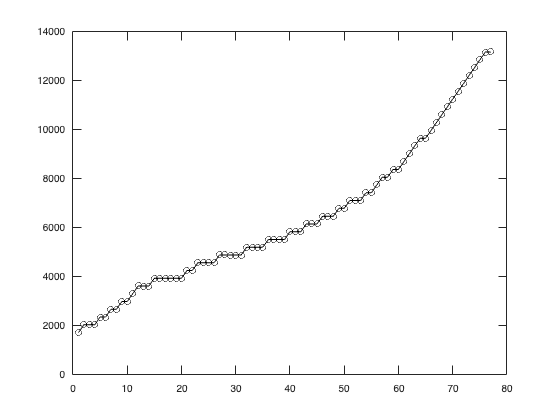

figure(k)
plot(data.gridID(idx,:),'ko-')
hold on


%axis([40 80 6000 14000]);
aa = sigy*YTest(index)+muy;

Unrecognized function or variable 'sigy'.

plot(aa,'b+-')
hold on
bb = smooth(sigy*YPred(index)+muy)
plot(bb,'r.-');

hold off
legend("Original","Test","Predicted")
title(num2str(name), 'FontSize',15)
xlabel('time', 'FontSize', 15);
ylabel('Grid ID', 'FontSize', 15);
%text(1,12000,name,"HorizontalAlignment","left","VerticalAlignment","bottom")

legend("Position",[0.73894,0.18351,0.14286,0.090476], 'FontSize',12)

we can save the image in a file folder

%saveas(figure(k),fullfile('/Users/julesbyronmari/Desktop/PHYSICS 200/results/grid results',[num2str(name) '.png']))



## creating new grid basis

we will use this new grid basis to transpose the predicted frid locations to geo coordinates

gridLat = transpose(round(min(data.Lat)):1:round(max(data.Lat)))
gridLong = transpose(round(min(data.Long)):1:round(max(data.Long)))

create a table

[gridA,gridB] = meshgrid(gridLat,gridLong);
gridc=cat(2,gridA',gridB');
grid_d=reshape(gridc,[],2);

newLat = grid_d(:,1)
newLong = grid_d(:,2)
datanew = array2table([newLat, newLong])
datanew.newgridID = floor(datanew.Var1 - lat_min) * long_interval  + floor(datanew.Var2 - long_min);
datanew.newgridID = round(datanew.newgridID)

## find coordinates of predicted grid from new grid

for l = 1:1:length(bb)
    loc=find(datanew.newgridID==round(bb(l)));
    if isempty(loc)==1
        loc=[];
    else
        predlat(l) = datanew.Var1(find(datanew.newgridID==round(bb(l))));
        predlong(l) = datanew.Var2(find(datanew.newgridID==round(bb(l))));
    end
end
pred_coordinates = [nonzeros(predlat'), nonzeros(predlong')]
pred_lat = pred_coordinates(:,1);
pred_long = pred_coordinates(:,2);

find the coordinates of the test grid

test_lat = data.Lat(data.unique_key==name)
test_long = data.Long(data.unique_key==name)
figure(k)
geoplot(test_lat,test_long,'.-')
 hold on
geoplot(pred_lat,pred_long,'o-')
hold on
geolimits([-20 60],[70 200])
legend("Original","Predicted")
title (num2str(name))
hold off
%saveas(figure(k),fullfile('/Users/julesbyronmari/Desktop/PHYSICS 200/results/geoplot results',[num2str(name) '.png']))

comparison of coordinates latitude

figure(k)
plot (test_lat)
hold on
plot (pred_lat)
legend("Original","Predicted")
title (['LATITUDE-' num2str(name)] )
%ylabel(Latitude)
hold off
%saveas(figure(k),fullfile('/Users/julesbyronmari/Desktop/PHYSICS 200/results/coordinates results',['latitude' num2str(name) '.png']))

comparison of coordinates longitude

figure(k)
plot (test_long)
hold on
plot (pred_long)
legend("Original","Predicted")
title (['LONGITUDE-' num2str(name)])
%ylabel(Longitude)
hold off
%saveas(figure(k),fullfile('/Users/julesbyronmari/Desktop/PHYSICS 200/results/coordinates results',['longitude' num2str(name) '.png']))

Save as .csv file.

% towrite = cell2mat(struct2cell(info))'
% writematrix(towrite,"One_LSTM_layers.csv","delimiter",",")

Save as .mat file.

% save('One_LSTM_layers.mat','-struct','info')

Check if the file was saved correctly.

% disp('Contents of One_LSTM_layers.mat:')
% whos('-file','One_LSTM_layers.mat')